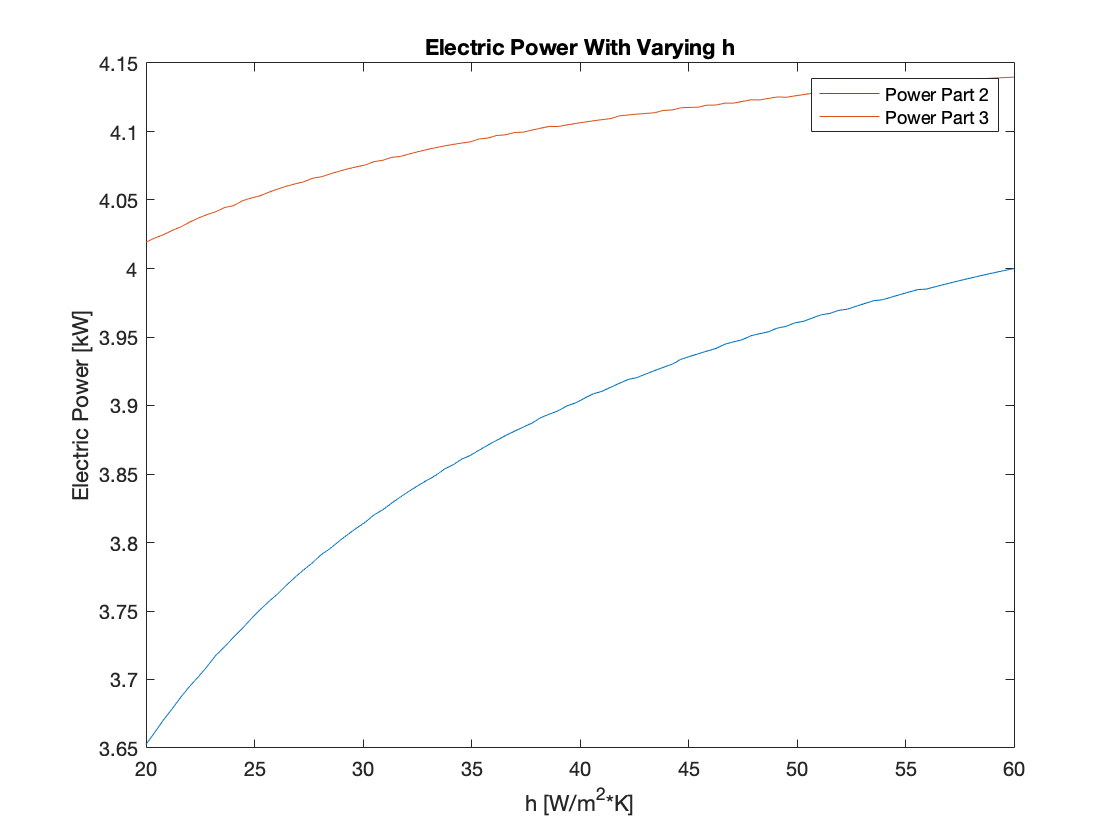

%Given Values
A = 30; %m^2
Gs = 700; % W/m^2
alpha_s = .95;
Tinf = 26 + 273.15; %K
Tsurr = Tinf;
epsilon = .76;
sigma = 5.67*10^-8; %W/M^2*K^4

%Establish h and use it to find Tp for parts 2 and 3
h = linspace(20,60);
Tp1 = [];
Tp2 = [];
for i = 1:numel(h)
    temp1 = Tpcalculator1(h(i));
    temp2 = Tpcalculator2(h(i));
    Tp1(i) = temp1;
    Tp2(i) = temp2;
end

%Calculate the Electric Power output for parts 2 and 3
P_elec1 = alpha_s.*Gs*A.*(.6-.0013.*Tp1);
P_elec2 = alpha_s.*Gs*A.*(.6-.0013.*Tp2);

%Plot the two Electric Power outputs
clf
plot(h,P_elec1/1000)
hold on
plot(h,P_elec2/1000)
hold off
xlabel("h [W/m^2*K]")
ylabel("Electric Power [kW]")
title('Electric Power With Varying h')
legend('Power Part 2', 'Power Part 3')


% Part 2 Explanation: 
% As the h value increases, q_convection becomes greater.
% When q_convection increases, the Tp decreases. From the
% given power equation, we know that P_elec increases as Tp
% decreases
% 
%
% Part 3 Explanaiton: 
% The electric power increases by about .5-.15 kW which is a 
% substancial amount. It increases considerably because Tp 
% decreases a noticeable amount when there is less Ein due to 
% no irradation from the surroundings. 

%Function to find Tp in part 2

function Tp = Tpcalculator1(h)
%Given Values
A = 30; %m^2
Gs = 700; % W/m^2
alpha_s = .95;
Tinf = 26 + 273.15; %K
Tsurr = Tinf;
epsilon = .76;
sigma = 5.67*10^-8; %W/M^2*K^4

%Create a guess value for Tp by ignoreing the TP^4 term
syms  Tp
eqn = alpha_s*Gs*(.4+.0013*Tp) == epsilon*sigma*(-Tsurr^4) + h*(Tp - Tinf);
Guess = double(solve(eqn, Tp));

part1 =  alpha_s*Gs*(.4+.0013*Guess);
part2 = epsilon*sigma*(Guess^4-Tsurr^4) + h*(Guess - Tinf);

%Iterate through gusses until the equation is balanced
while [abs(part1) - abs(part2)] < 1
    Guess = Guess - .05;
    part1 =  alpha_s*Gs*(.4+.0013*Guess);
    part2 = epsilon*sigma*(Guess^4-Tsurr^4) + h*(Guess - Tinf);
end
Tp = Guess;
end


%Function to find Tp for part 3
function Tp = Tpcalculator2(h)
%Given Values
A = 30; %m^2
Gs = 700; % W/m^2
alpha_s = .95;
Tinf = 26 + 273.15; %K
Tsurr = Tinf;
epsilon = .76;
sigma = 5.67*10^-8; %W/M^2*K^4

%Create a guess value for Tp by ignoreing the TP^4 term
syms  Tp
eqn = alpha_s*Gs*(.4+.0013*Tp) == h*(Tp - Tinf);
Guess = double(solve(eqn, Tp));

part1 =  alpha_s*Gs*(.4+.0013*Guess);
part2 = epsilon*sigma*(Guess^4) + h*(Guess - Tinf);

%Iterate through gusses until the equation is balanced
while [abs(part1) - abs(part2)] < 1
    Guess = Guess - .05;
    part1 =  alpha_s*Gs*(.4+.0013*Guess);
    part2 = epsilon*sigma*(Guess^4) + h*(Guess - Tinf);
end
Tp = Guess;
end